% data = load('lidarData.mat');
% lbl = load('lidarLabel.mat');

## Part 1: Create PointCloud

[X,Y] = meshgrid(linspace(-0.1,1.1,25),linspace(-0.1,2.1,40));
Z = (X>=0 & X<=1 & Y>=0 & Y<=2).*(X.^2+Y.^3);
% surf(X,Y,Z)

pc = pointCloud([X(:) Y(:) Z(:)])

pc =   pointCloud with properties:

     Location: [1000×3 double]
        Count: 1000
      XLimits: [-0.1000 1.1000]
      YLimits: [-0.1000 2.1000]
      ZLimits: [0 8.7496]
        Color: []
       Normal: []
    Intensity: []


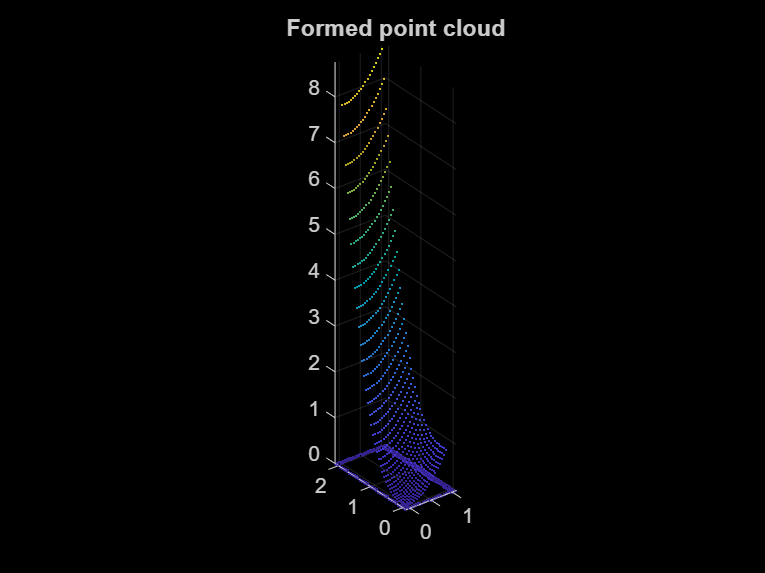

pcshow(pc)
title('Formed point cloud');

## Part 2.1: Transformation

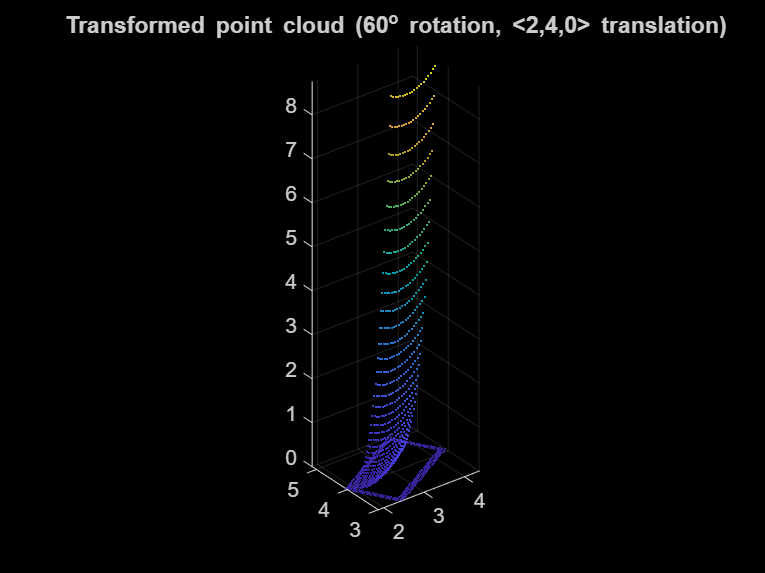

tform = rigid3d(rotz(60),[2,4,0]);
pc_tf = pctransform(pc,tform);
pcshow(pc_tf);
title('Transformed point cloud (60^o rotation, <2,4,0> translation)');

## Part 2.2-2.3: ICP

% True transform
true_transform = tform.T

true_transform =     0.5000   -0.8660         0         0
    0.8660    0.5000         0         0
         0         0    1.0000         0
    2.0000    4.0000         0    1.0000


% ICP estimation of transform matrix
[tf,~,~] = pcregistericp(pc,pc_tf,MaxIterations=100,Tolerance=[0.01,0.01],Verbose=true);

--------------------------------------------
ICP Iteration 1 :
Finding point correspondences ...Completed.
Estimating transformation ...Completed.
Change in translation: 2.9624. Change in rotation: 10.5779. Root mean square error: 0.89781

--------------------------------------------
ICP Iteration 2 :
Finding point correspondences ...Completed.
Estimating transformation ...Completed.
Change in translation: 0.32864. Change in rotation: 1.1903. Root mean square error: 0.48579

--------------------------------------------
ICP Iteration 3 :
Finding point correspondences ...Completed.
Estimating transformation ...Completed.
Change in translation: 0.16719. Change in rotation: 0.74667. Root mean square error: 0.40954

--------------------------------------------
ICP Iteration 4 :
Finding point correspondences ...Completed.
Estimating transformation ...Completed.
Change in translation: 0.10729. Change in rotation: 0.80262. Root mean square error: 0.37641

--------------------------------------

predicted_transform = tf.T

predicted_transform =     0.5000   -0.8660    0.0000         0
    0.8660    0.5000   -0.0000         0
   -0.0000    0.0000    1.0000         0
    2.0000    4.0000   -0.0000    1.0000


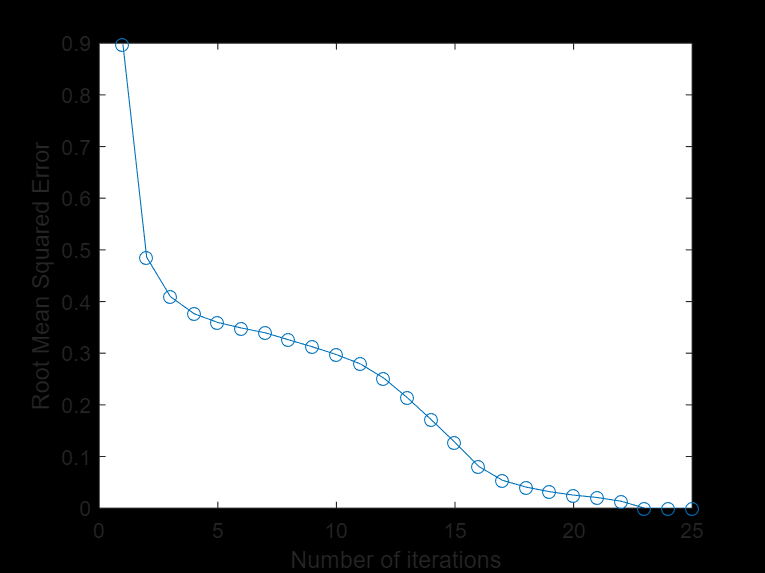

% Plot out iteration error
e = zeros(26,1);
for i=1:26
    [~,~,e(i)] = pcregistericp(pc,pc_tf,MaxIterations=i,Tolerance=[0.01,0.05]);
end
plot(e,'-o');
title('Error Across Iterations');
xlabel('Number of iterations');
ylabel('Root Mean Squared Error')

function r = roty(t)
    dt = deg2rad(t);
    r = [cos(dt) 0 sin(dt);
        0        1       0;
        -sin(dt) 0 cos(dt)];
end
function r = rotx(t)
    dt = deg2rad(t);
    r = [1  0        0;
         0  cos(dt) -sin(dt);
         0  sin(dt)  cos(dt)];
end
function r = rotz(t)
    dt = deg2rad(t);
    r = [cos(dt) -sin(dt) 0;
        sin(dt)   cos(dt) 0;
        0         0       1];
end